# Harmonifilter

*Fred-Johan pettersen, Yppersteprest av Teknologi og innovasjonsklinikken, i all beskjedenhet.*

## Introduksjon

### Problemstilling

Akselerometermålinger på LVAD har en del harmoniske  signaler samt en del signaler som kan minne om harmoniske, men som har andre kilder. Det er mulig at noen har sitt opphav i miksing av flere kilder i ulineære deler av oppsettet. Disse harmoniske må fjernes om man skal se på Itais Non Harmonic Amplitude (NHA) for å lære mer om hvordan tromber, embolier, flow, et cetera påvirker NHA.

### Løsning

Harmonifilteret er et filter som fjerner harmoniske komponenter fra et signal. Filteret fjerner også alt som ser ut som harmoniske signaler. Det virker ved å foreta en FFT av signalet for å dra ut spektrogrammet. Amplitudedelen blir så analysert av findpeaks() for å finne ut de uønskede harmoniske komponentene. Disse blir så brukt for å generere multifrekvens notchfilter som fjerner de uønskede frekvensene.

## Implementasjon

### Data

Om vi har data er jo det bra. Last de inn in her, eller generer eget datasett.

% Load data
clear;
datafile = "datafil";
makeSignal = 1;
if exist("datafile", "file")
    load("datafile.mat");
    if exist("signal", "var") ...
       && exist("fSample", "var")
        nSamples = length(signal);
        makeSignal = 0;
    end
end

Vi trenger er datasett med støy noen solide frekvenskomponenter og frekvensorientert støy. Først må vi spesifisere i frekvensplanet.

% If no variable 'signal' exist, genereate it:
if makeSignal
    f1 = 50;                            % First harmonic frequency in Hz.
    fHarm = [1 2 2.7 3 4];              % List of harmonics.
    fHarmAmp = [1 0.8 0.75 0.1 0.7];    % Amplitudes of harmonics.

    fNha = [2 3 5];                     % NHA signal peak frequencies.
    fNhaAmp = [0.5 0.5 0.7];            % Corresponding amplitudes.
    fNhaBw = [1 0.5 2];               % Corresponding bandwidths.

    noiseAmp = 0.1;                     % Noise amplitude.

Så må vi generere et de individuelle harmoniske tidsplansignalene.

    fSample = 4000;                     % Sample rate [S/s].
    tMax = 10;                          % Maximum time [s].

    nSamples = (fSample*tMax)+1;        % Number of samples.
    ts = linspace(0, tMax, nSamples)';  % Time-stamps.
    ts2Pi = 2 * pi * ts;                % Time-stamps in more convenient form multiplied by 2 pi.
    signalHarm = zeros(nSamples, 1);    % Allocate memory for speed.
    for i = 1:length(fHarm)
        signalHarm = signalHarm + fHarmAmp(i) * sin(fHarm(i) * f1 * ts2Pi);
    end

Deretter må vi legge på ønskede NHA signaler. Disse lager vi ved å filtrere tilfeldig støy med båndpassfilter.

    signalNha = zeros(nSamples, 1);     
    for i = length(fNha)
        tmpFilter = designfilt('bandpassfir', ...
            'FilterOrder', 100, ...
            'CutoffFrequency1', f1*(fNha(i) - 0.5*fNhaBw(i)), ...
            'CutoffFrequency2', f1*(fNha(i) + 0.5*fNhaBw(i)), ...
            'SampleRate', fSample);
        signalNha = signalNha + filter(tmpFilter,randn(nSamples, 1));
    end

 Og til slutt mekker vi litt tilfeldig bakgrunnsstøy.

    signalNoise = noiseAmp * randn(nSamples, 1);

La oss ta en titt på signalene.

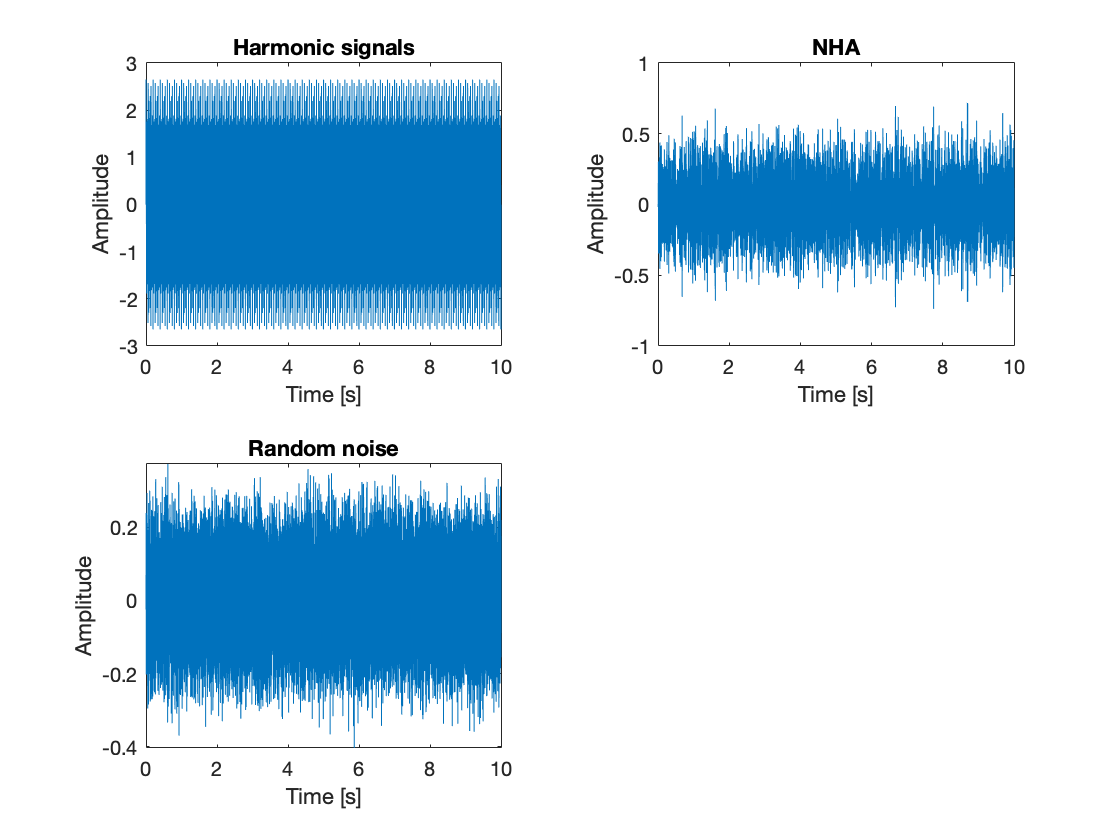

    signal = signalHarm + signalNha + signalNoise;

    figure(1); clf; tiledlayout('flow');
    nexttile;
    plot(ts, signalHarm);
    title("Harmonic signals");
    xlabel("Time [s]"); ylabel("Amplitude");

    nexttile;
    plot(ts, signalNha);
    title("NHA");
    xlabel("Time [s]"); ylabel("Amplitude");

    nexttile;
    plot(ts, signalNoise);
    title("Random noise");
    xlabel("Time [s]"); ylabel("Amplitude");
end

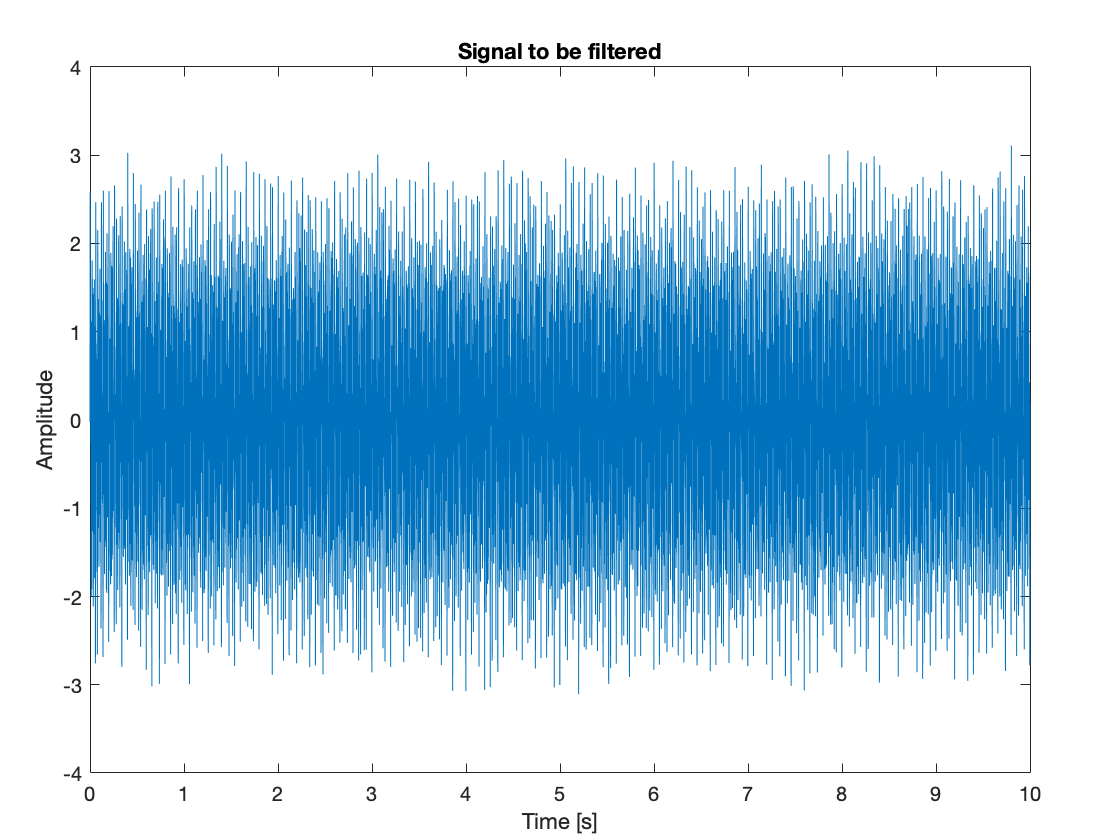


clf;
plot(ts, signal);
title("Signal to be filtered");
xlabel("Time [s]"); ylabel("Amplitude");

### Finne harmoniske

Nå har vi et signal som kommer fra eller *kunne* komme fra en LVAD. La oss se på hvilke frekvenser vi vil ta vekk. Kjernen i det å finne riktige "harmoniske" ligger i parametrene til funksjonen `findpeaks()`.

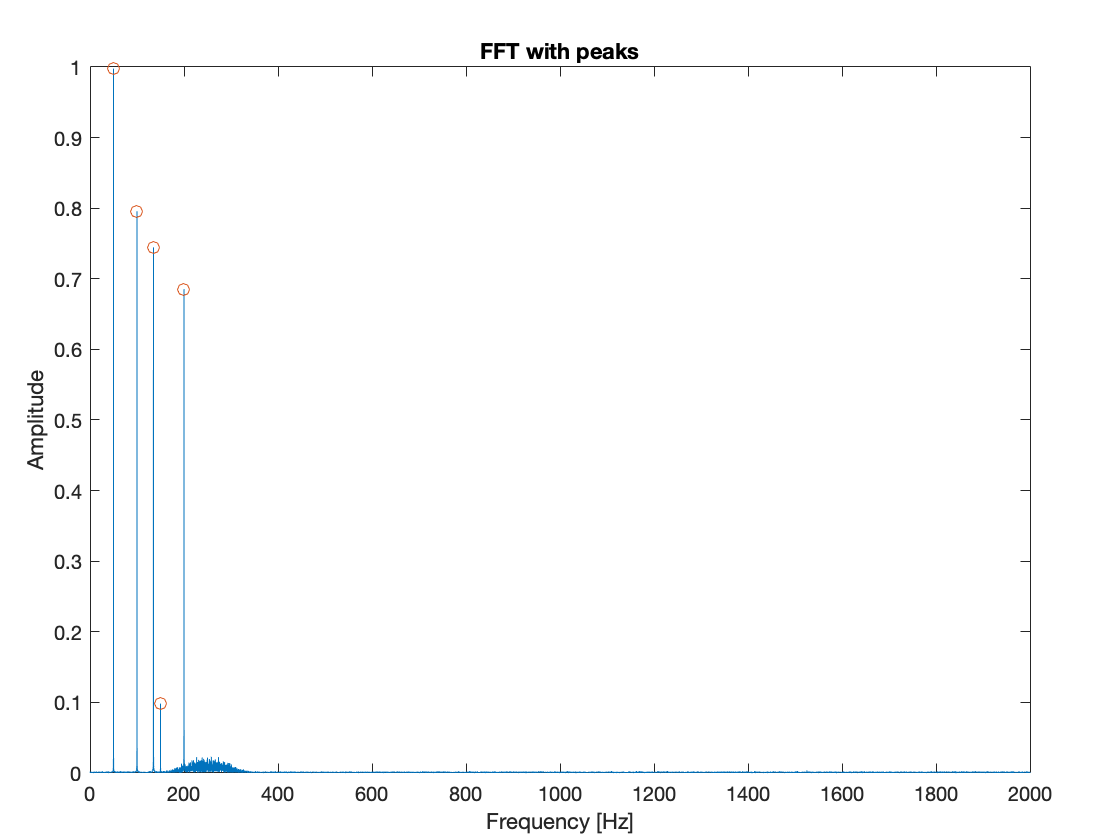

if mod(length(signal), 2) > 0                   % Ensure even number of samples.
    signal(end+1) = signal(end);
    ts(end+1)=ts(end) + 1/fSample;
end
fftA = fft(signal);                             % FFT of signal.
fftA = abs(fftA/nSamples);
fftA = fftA(1:floor(nSamples/2)+1);
fftA(2:end-1) = 2 * fftA(2:end-1);
f = fSample*(0:(nSamples/2))/nSamples;

% Find peaks.
[peakMags, peakFreqs, ~, ~] = findpeaks(fftA, f,'MinPeakProminence',0.05);

%Show result
clf;
plot(f, fftA, '-', peakFreqs, peakMags, 'o');
title("FFT with peaks");
xlabel("Frequency [Hz]"); ylabel("Amplitude");

### Lage filter

Nå kan vi lage oss et knippe filter. Det er helt sikkert mulig å slå disse sammen på en elegant måte, men det er opp til nestemann.

nHarmonics = length(peakFreqs);
notchWidth = 5;                 % Notchwidth as a percentage of notch frequency.
for i = 1:nHarmonics
    notchFilt(i) = designfilt(...
        'bandstopiir', ...
        'FilterOrder', 8, ...
        'HalfPowerFrequency1', peakFreqs(i)*(1-notchWidth/200), ...
        'HalfPowerFrequency2', peakFreqs(i)*(1+notchWidth/200), ...
        'SampleRate',fSample);
end

### Filtrere data

Vi har et signal, vi har analysert det og vi har laget et knippe med tilhørende notch filter. Da filtrerer vi.

signalFiltered = signal;
if nHarmonics > 0
    for i = 1:nHarmonics
        signalFiltered = filter(notchFilt(i), signalFiltered);
    end
end

% Doing an FFT on the filtered signal.
fftB = fft(signalFiltered);
fftB = abs(fftB/nSamples);
fftB = fftB(1:floor(nSamples/2)+1);
fftB(2:end-1) = 2 * fftB(2:end-1);

### Presentere

Nå burde vi ha fine signaler. 

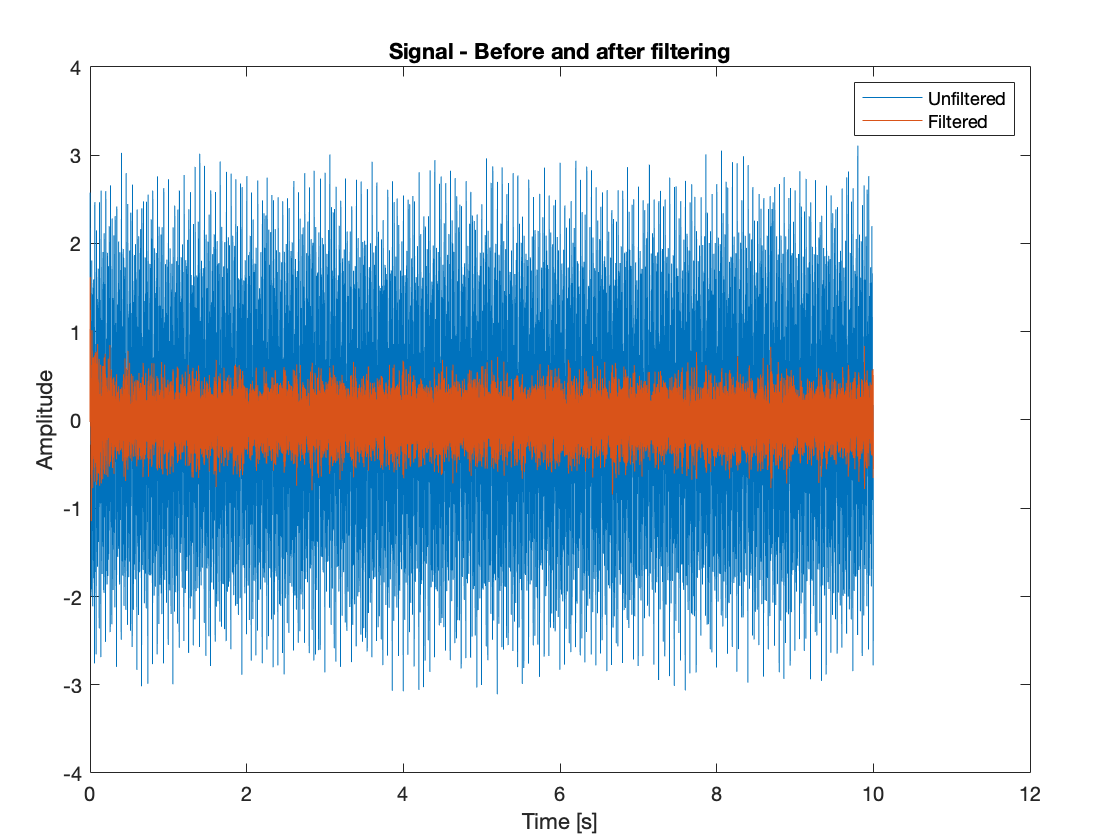

clf;
plot(ts, signal, ts, signalFiltered);
title("Signal - Before and after filtering");
legend("Unfiltered", "Filtered");
xlabel("Time [s]"); ylabel("Amplitude");

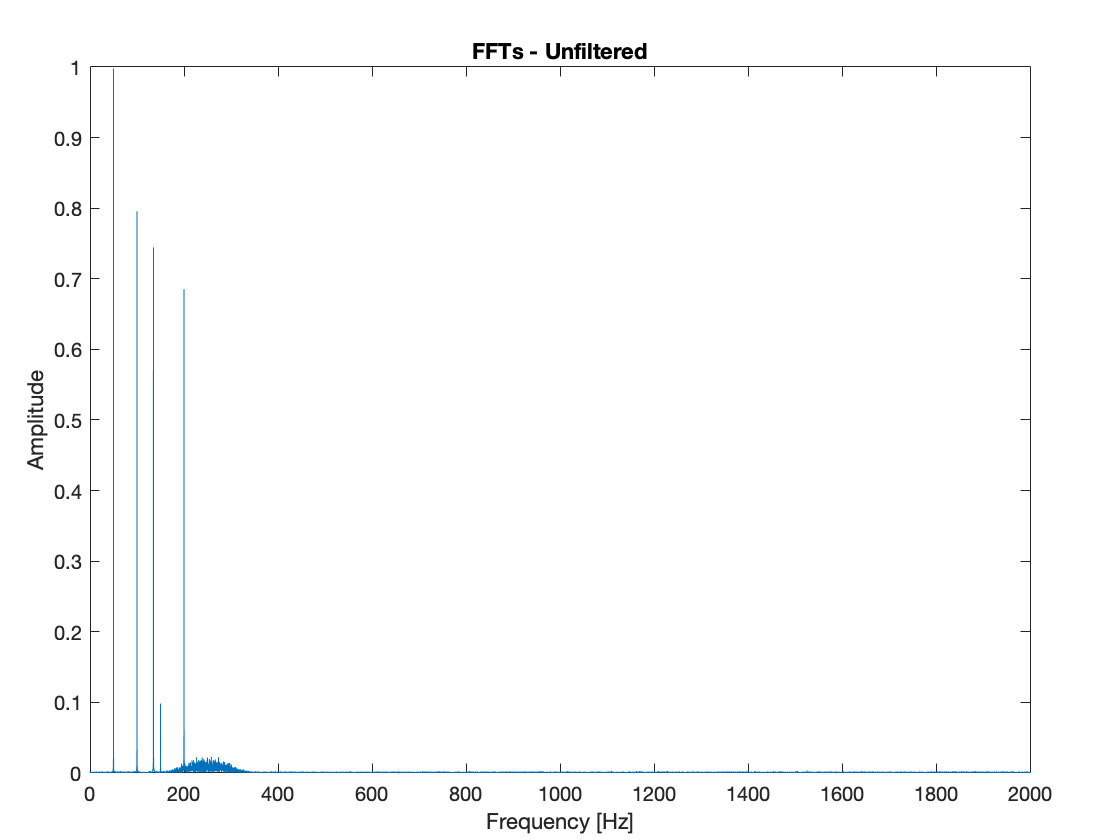


clf;
plot(f, fftA);
title("FFTs - Unfiltered");
xlabel("Frequency [Hz]"); ylabel("Amplitude");

nexttile;

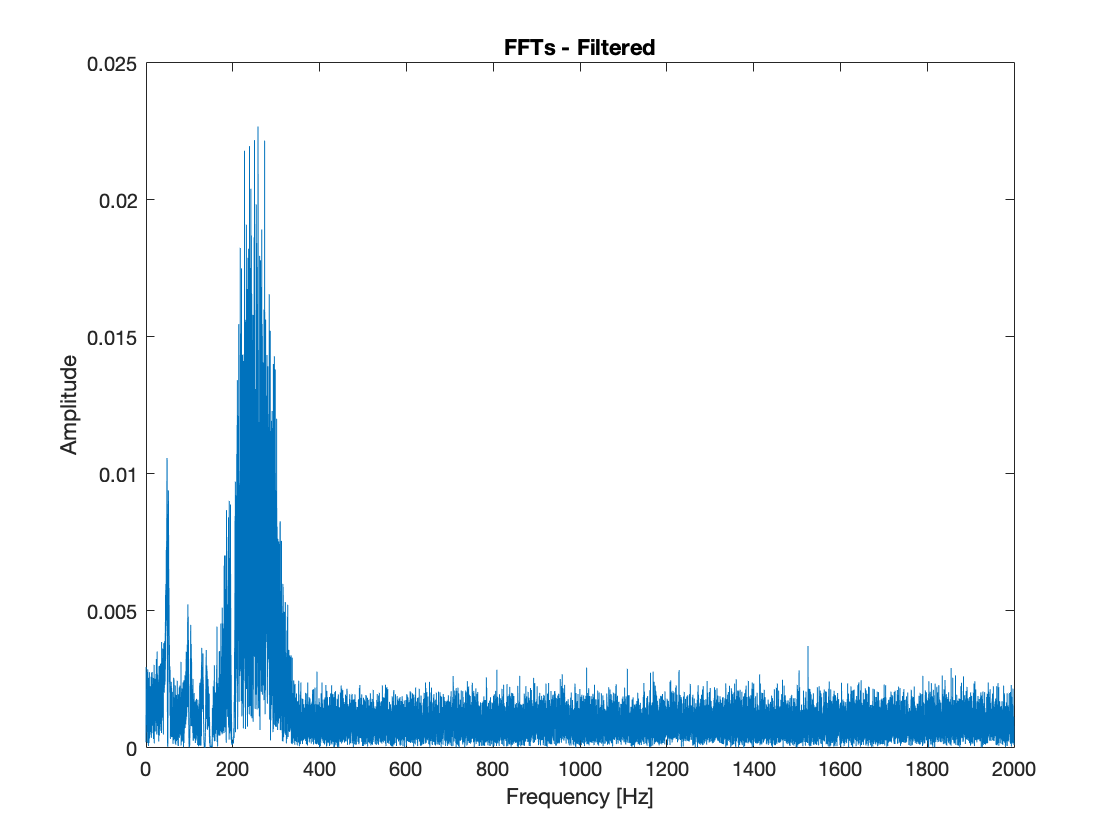

plot(f, fftB);
title("FFTs - Filtered");
xlabel("Frequency [Hz]"); ylabel("Amplitude");

## Diskusjon og konklusjon

### Diskusjon

Her er et generert signal benyttet, men i prinsippet burde det ikke bety noe. Enhet på signalene er også utelatt, men det betyr ingenting med tanke på demonstrasjon av prinsippet.

### Konklusjon

Adaptiv harmonifjerning ser da virkelig ut til å være en ytterst genial idé. Dette er rett og slett en maktdemonstrasjon.